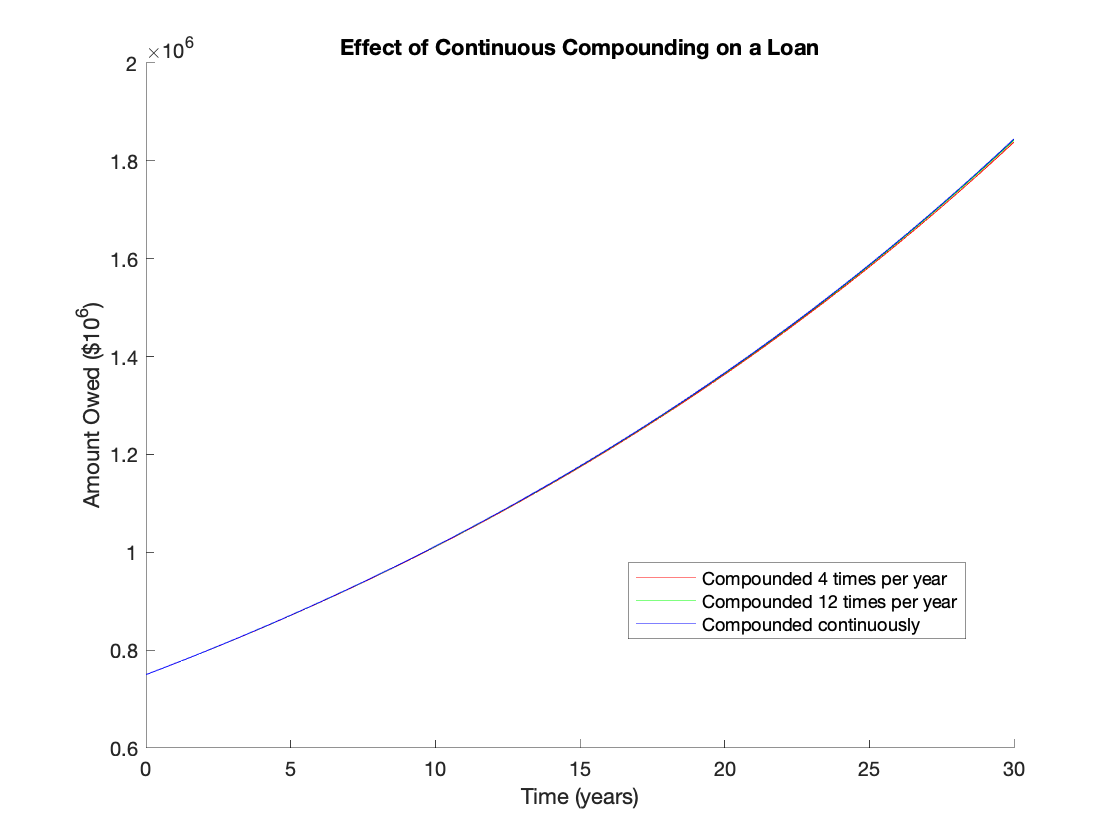

syms A1(t) A2(t) A4(t) A12(t) Ae(t)
ts = linspace(0,30,50);
A1(t) = 750000*(1+0.03/1)^(1*t);
A2(t) = 750000*(1+0.03/2)^(2*t);
A4(t) = 750000*(1+0.03/4)^(4*t);
A12(t) = 750000*(1+0.03/12)^(12*t);
Ae(t) = 750000*exp(0.03*t);
figure;
title('Effect of Continuous Compounding on a Loan')
hold on
plot(ts,A4(ts),'r',ts,A12(ts),'g',ts,Ae(ts),'b')
xlabel("Time (years)")
ylabel("Amount Owed ($10^6)")
legend('Compounded 4 times per year','Compounded 12 times per year','Compounded continuously',"location","best")